ADALINE

vector de X para entrenamiento

X = [-1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1, -1;
    0.4329, 0.3024, 0.1349, 0.3374, 1.1434, 1.3749, 0.7221, 0.4403, -0.5231, 0.3255, 0.5824, 0.1340, 0.1480, 0.7359, 0.7115, 0.8251, 0.1569, 0.0033, 0.4243, 1.0490, 1.4276, 0.5971, 0.8475, 1.3967, 0.0044, 0.2201, 0.6300, -0.2479, -0.3088, -0.5180, 0.6833, 0.4353, -0.1069, 0.4662, 0.8298;
    -1.3719, 0.2286, -0.6445, -1.7163, -0.0485, -0.5071, -0.7587, -0.8072, 0.3548, -2.0000, 1.3915, 0.6081, -0.2988, 0.1869, -1.1469, -1.2840, 0.3712, 0.6835, 0.8313, 0.1326, 0.5331, 1.4865, 2.1479, -0.4171, 1.5378, -0.5668, -1.2480, 0.8960, -0.0929, 1.4974, 0.8266, -1.4066, -3.2329, 0.6261, -1.4089;
    0.7022, 0.8630, 1.0530, 0.3670, 0.6637, 0.4464, 0.7681, 0.5154, 0.2538, 0.7112, -0.2291, 0.4450, 0.4778, -0.0872, 0.3394, 0.8452, 0.8825, 0.5389, 0.2634, 0.9138, -0.0145, 0.2904, 0.3179, 0.6443, 0.6099, 0.0515, 0.8591, 0.0547, 0.8659, 0.5453, 0.0829, 0.4207, 0.1856, 0.7304, 0.3119;
    -0.8535, 2.7909, 0.5687, -0.6283, 1.2606, 1.3009, -0.5592, -0.3129, 1.5776, -1.1209, 4.1735, 3.2230, 0.8649, 2.3584, 0.9573, 1.2382, 1.7633, 2.8249, 3.5855, 1.9792, 3.7286, 4.6069, 5.8235, 1.3927, 4.7755, 0.7829, 0.8093, 1.7381, 1.5483, 2.3993, 2.8864, -0.4879, -2.4572, 3.4370, 1.3235];

Vector de d para entrenamiento

d = [1; -1; -1; -1; 1; 1; 1; 1; -1; 1; -1; -1; 1; 1; -1; -1; 1; -1; -1; 1; 1; -1; -1; 1; -1; 1; -1; 1; -1; 1; 1; 1; -1; -1; -1];

W = rand(5, 1);
disp("El vector inicial es");

El vector inicial es


disp(W);

    0.2518
    0.2904
    0.6171
    0.2653
    0.8244



Taza de aprendizaje 

Eta = 0.0025;

Precisión requerida para la convergencia

epsilon = 1e-6;

Contador y limitador de epocas

Epoca = 0;
max_epocas = 10000;

 Número de muestras (P)

P = length(d);

 Función de Error Cuadrático Medio (MSE)

E_act = 0;
for k = 1:P
    u = W' * X(:,k);
    E_act = E_act + (d(k) - u)^2;
end
E_act = E_act / P;

Para graficar el error en cada epoca

mse1 = E_act;

Entrenamiento de Adaline 1

while Epoca < max_epocas

    % 6.1
    E_ant = E_act ; 

    % 6.2
    for i = 1:P
        u = W' * X(:,i); % 6.2.1 
        W = W + Eta * (d(i) - u) * X(:,i); % 6.2.2
    end 

    % 6.3
    Epoca = Epoca + 1;

    % 6.4
    E_act = 0;
    for k = 1:P
        u = W' * X(:,k);
        E_act = E_act + (d(k) - u)^2;
    end
    E_act = E_act / P;
    mse1 = [mse1, E_act];

    % Condicion de convergencia
    if abs(E_act - E_ant) <= epsilon
        break;

    end
end

disp('Total de epocas:');

Total de epocas:


disp(Epoca);

   891



disp("El vector resultante es:");

El vector resultante es:


disp(W);

   -1.8131
    1.3128
    1.6423
   -0.4278
   -1.1778



Ya que tenemos nuestro primer Error por cada epoca, vamos a sacar la segunda etapa de entrenamiento para comparar

W2 = rand(5, 1); 
disp('El vector inicial 2 es:');

El vector inicial 2 es:


disp(W2);

    0.9827
    0.7302
    0.3439
    0.5841
    0.1078



Epoca2 = 0;


 Función de Error Cuadrático Medio del segundo entrenamiento(MSE2)

E_act2 = 0;
for k = 1:P
    u = W2' * X(:,k);
    E_act2 = E_act2 + (d(k) - u)^2;
end
E_act2 = E_act2 / P;

mse2 = E_act2;

% Entrenamiento 2
while Epoca2 < max_epocas

    % 6.1
    E_ant2 = E_act2; 

    % 6.2
    for i = 1:P
        u = W2' * X(:,i); 
        W2 = W2 + Eta * (d(i) - u) * X(:,i); 
    end 

    % 6.3
    Epoca2 = Epoca2 + 1;

    % 6.4
    E_act2 = 0;
    for k = 1:P
        u = W2' * X(:,k);
        E_act2 = E_act2 + (d(k) - u)^2;
    end
    E_act2 = E_act2 / P;

    %se guarda el error por epoca para la tablita
    mse2 = [mse2, E_act2];

    % Condicion de convergencia
    if abs(E_act2 - E_ant2) <= epsilon
        break;
    end
end

disp('Total de epocas Proceso 2:');

Total de epocas Proceso 2:


disp(Epoca2);

   929



disp('El vector resultante 2 es:');

El vector resultante 2 es:


disp(W2);

   -1.8131
    1.3129
    1.6424
   -0.4276
   -1.1778



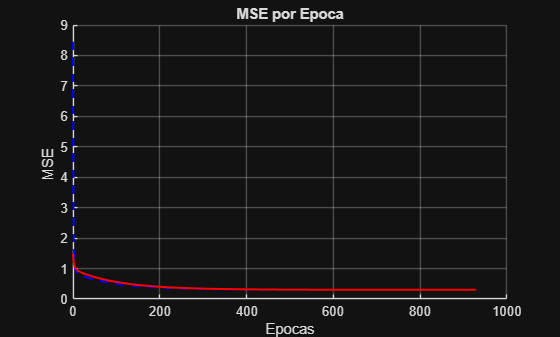


% ==========================================
% GRÁFICA COMPARATIVA (PROCESO 1 vs PROCESO 2)
% ==========================================
figure(1);
hold on;
grid on;

% Graficar ambas curvas
% Se usa 0:length-1 para que el eje X empiece en la época 0
plot(0:length(mse1)-1, mse1, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Proceso 1');
plot(0:length(mse2)-1, mse2, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Proceso 2');

title('MSE por Epoca');
xlabel('Epocas');
ylabel('MSE')
hold off;